clc
clear

no_of_file_to_average = 12;

filepath = 'C:\New Folder'; %opens a diolouge box for user to select file directory
myFiles = dir(fullfile(filepath)); %returns a struct containing the files containied in the directory and their properites, we can extract the number of files and file names from this

newpath = strcat(filepath,'\procesed\radar_images\'); %creates a string that is used to make the 'proccessed' folder
mkdir(newpath); %makes the proccessed folder

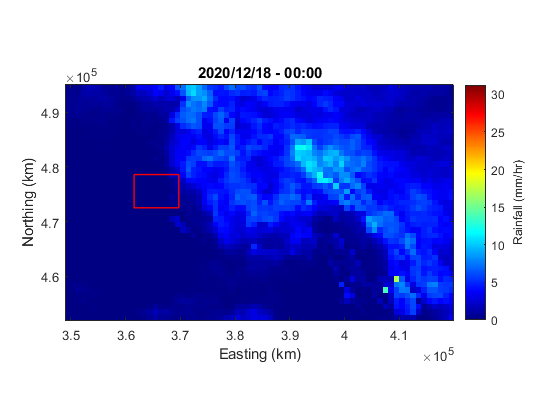


noOfFiles = (size(myFiles))-3; %returns the number of files in the directory
noOfFiles = noOfFiles(:,1); %removes the random '1' from the noOfFiles

times = zeros(1,(noOfFiles)/no_of_file_to_average);
rainfall_mm_array = zeros(1,(noOfFiles)/no_of_file_to_average);

rainfall_mm_array_one_hour = zeros(1,no_of_file_to_average);

count = 0;
the_hour = 0;


for i = 3:noOfFiles+2 %loops round until all the files have been proccessed + two to include random .. and . files
    
    FileName = myFiles(i).name; %extracts the file name from the myFiles struct
    fullFilePath = fullfile(filepath,FileName); %combines the file path with the file name
    
    % read the uncompressed NIMROD composite uk-1km rain radar data file
    [int_gen_hd, rl_gen_hd, rl_datsp_hd, char_hd, int_datsp_hd,rr_dat_mat] = rdnim1km( fullFilePath );
    
    xmax = int_gen_hd(19);
    rr_dat_mat(1:20,xmax-19:xmax) = 600;
    rr_dat_mat = rr_dat_mat/32; %converts from 1/32mm/hr to mm/hr
    
    clims = [ 0 31.25 ]; %sets the colour bar lims
    xg = linspace(rl_datsp_hd(2),rl_datsp_hd(4),int_gen_hd(19)); %create linear spacing for the xaxis
    yg = linspace(rl_datsp_hd(1),rl_datsp_hd(5),int_gen_hd(18)); %create linear spacing for the yaxis
    
    %these are the co-ordinates for a bounding box in the rain radar window
    %I have included only 2 as you can extrapolaet the other co-ordinates
    %from 2 corners, OSGB36 National Grid format
    top_left_coordinate_northing =  494605;
    top_left_coordinate_easting = 349717;
    
    bottom_right_coordinate_northing = 452530;
    bottom_right_coordinate_easting = 419548;
    
    %finds the row/colum indexes for the bounding box
    [~,idx]=min(abs(yg-top_left_coordinate_northing));
    minVal=yg(idx);
    top_left_northing_coordinate_index = find(yg==minVal);
    
    [~,idx]=min(abs(xg-top_left_coordinate_easting));
    minVal=xg(idx);
    top_left_easting_coordinate_index = find(xg==minVal);
    
    [~,idx]=min(abs(yg-bottom_right_coordinate_northing));
    minVal=yg(idx);
    bottom_right_coordinate_northing_index = find(yg==minVal);
    
    [~,idx]=min(abs(xg-bottom_right_coordinate_easting));
    minVal=xg(idx);
    bottom_right_coordinate_easting_index = find(xg==minVal);
    
    %cuts the big radar picture down into a smaller box
    xg_cut = xg(top_left_easting_coordinate_index:bottom_right_coordinate_easting_index);
    yg_cut = yg(top_left_northing_coordinate_index:bottom_right_coordinate_northing_index);
    rr_dat_mat_cut = rr_dat_mat(top_left_northing_coordinate_index:bottom_right_coordinate_northing_index,top_left_easting_coordinate_index:bottom_right_coordinate_easting_index);
    
    
    %takes the file name and reformats it for title and file naming
    Zfname = strtrim(FileName(1:12));
    %title formatting
    year = strtrim(Zfname(1:4));
    month = strtrim(Zfname(5:6));
    day = strtrim(Zfname(7:8));
    hour = strtrim(Zfname(9:10));
    minute = strtrim(Zfname(11:12));
    date_time = strcat(year,'/',month,'/',day,32,'-',32,hour,':',minute);
    
    
    
    % formats and displays the cut rain radar data image
    img = imagesc(xg_cut,yg_cut,rr_dat_mat_cut,clims);
    colormap(jet);
    xlabel('Easting (km)');
    ylabel('Northing (km)');
    width = size(xg_cut,2);
    height = size(yg_cut,2);
    pbaspect([width height 1]);
    axis xy;
    title(date_time);
    h = colorbar; set(get(h,'label'),'string','Rainfall (mm/hr)');
    hold on
    
    %creates a smaller box within the larger plot of catchment area for
    %rainfall
    
    bottom_right_coordinate_easting = 369717;
    top_left_coordinate_easting = 361548;
    bottom_right_coordinate_northing = 472530;
    top_left_coordinate_northing = 478605;
    
    x1 = bottom_right_coordinate_easting;
    x2 = top_left_coordinate_easting;
    y1 = bottom_right_coordinate_northing;
    y2 = top_left_coordinate_northing;
    
    x = [x1, x2, x2, x1, x1];
    y = [y1, y1, y2, y2, y1];
    catchment = plot(x, y, 'r-', 'LineWidth', 1);
 
    %creates the intial PNG file, this is overwritten by another PNG file
    %that has had the background removed for map underlay
    time_Vs_absorbtion_plot_name = strcat(newpath,Zfname,'.png');
    saveas(img, time_Vs_absorbtion_plot_name);
    
    %this creates a alpha cut map so it knows where to cut out the
    %background
    img2 = imread(time_Vs_absorbtion_plot_name);
    imgcut = img2(:,:,3);
    imgcut(imgcut<130.5) =500;
    imgcut(imgcut>131.5) = 500;
    imgcut(imgcut==131) = 0; %131 is the colour code for the blue background
    imwrite(img2,time_Vs_absorbtion_plot_name,'Alpha',imgcut);
end